## Problem 5:

Applications of various numerical integration methods(Random Interval Riemann sum / Riemann integration, Simpsons method, Trapezoidal method) and comparing their accuracies by using these methods on some crazy integrals.

## part 1: Obtaining the value of omega constant **Ω**.

**Ω **omega constant is a constant which satisfies the integrals mentioned below:

or

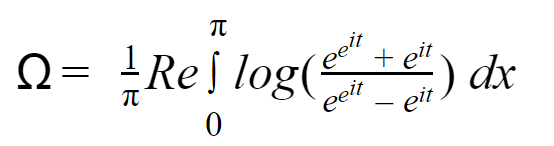

Where  **Ω **omega constant, 

Omega constant is a constant satisfying the below condition:

The value of  **Ω **is: 

Ref:

1) [https://en.wikipedia.org/wiki/Omega_constant](https://en.wikipedia.org/wiki/Omega_constant)

2) [https://math.stackexchange.com/questions/3027621/request-for-crazy-integrals](https://math.stackexchange.com/questions/3027621/request-for-crazy-integrals)

Now using the second integral, we will find the value of **Ω **using several numerical methods.

Below is the script for finding the estimated value of **Ω **using three different methods;

1) Random Interval Riemann Sum / Riemann Integration

2) Simpson Integration

3) Trapezoidal Integration

f = @(x) log((exp(exp(1i * x)) + exp(1i * x)) / (exp(exp(1i * x)) - exp(1i * x)));
a = 0;
b = pi;
n = 3e6;

omega_constant_riemann = (1/pi)*real(myRiemannSum(f, a, b, n));
fprintf("\nValue of Ω using Riemann sum/integration:\n Ω = %f", omega_constant_riemann)


Value of Ω using Riemann sum/integration:
 Ω = 0.567143


omega_constant_simpsons = (1/pi)*real(mySimpsons(f, a, b, n));
fprintf("\nValue of Ω using Simpsons integration:\n Ω = %f", omega_constant_simpsons)


Value of Ω using Simpsons integration:
 Ω = 0.000000


omega_constant_trapz= (1/pi)*real(myTrapezoidal(f, a, b, n));
fprintf("\nValue of Ω using Trapezoidal integration:\n Ω = %f", omega_constant_trapz)


Value of Ω using Trapezoidal integration:
 Ω = 0.567143

Observations:

Simpsons integration could not provide the answers and the rest could.

The reason can be that the function includes complex numbers for the integrations and there we can not use simpsons integration.

Prob 2: Using the value of π, get the value of e and compare these algorithms' error and efficiency.

Let's check these algorithms' accuracy by comparing the estimated values with actual value.

For that let's take a crazy integration mentioned below:

Here, using the value of π, we can obtain the value of e by the equation below:

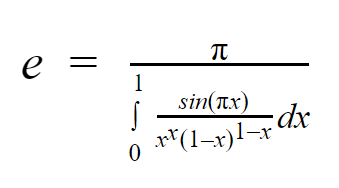

Below is the script of the above problem and comparison of different methods by their accuracies.

g = @(x) sin(pi .* x) ./ ((x .^ x) .* (1-x) .^ (1-x));
a = 0;
b = 1;
n = 3e6;
e_val = pi / myRiemannSum(g, a, b, n);
error_e = abs(e_val - exp(1));
fprintf("Method: %s\nn = %d\nestimated value of e = %f\nError: %E", "Riemann sum/integration", n, e_val, error_e);

Method: Riemann sum/integration
n = 3000000
estimated value of e = 2.718282
Error: 1.790359E-10

n = 1e7;
e_val = pi / myRiemannSum(g, a, b, n);
error_e = abs(e_val - exp(1));
fprintf("\nMethod: %s\nn = %d\nestimated value of e = %f\nError: %E", "Riemann sum/integration", n, e_val, error_e);


Method: Riemann sum/integration
n = 10000000
estimated value of e = 2.718282
Error: 1.560529E-11

n = 3e6;
e_val = pi / mySimpsons(g, a, b, n);
error_e = abs(e_val - exp(1));
fprintf("\nMethod: %s\nn = %d\nestimated value of e = %f\nError: %E", "Simpsons integration", n, e_val, error_e);


Method: Simpsons integration
n = 3000000
estimated value of e = 2.718282
Error: 4.440892E-16

n = 1e7;
e_val = pi / mySimpsons(g, a, b, n);
error_e = abs(e_val - exp(1));
fprintf("\nMethod: %s\nn = %d\nestimated value of e = %f\nError: %E", "Simpsons integration", n, e_val, error_e);


Method: Simpsons integration
n = 10000000
estimated value of e = 2.718282
Error: 0.000000E+00

n = 3e6;
e_val = pi / myTrapezoidal(g, a, b, n);
error_e = abs(e_val - exp(1));
fprintf("\nMethod: %s\nn = %d\nestimated value of e = %f\nError: %E", "Trapezoidal integration", n, e_val, error_e);


Method: Trapezoidal integration
n = 3000000
estimated value of e = 2.718282
Error: 2.815526E-13

n = 1e7;
e_val = pi / myTrapezoidal(g, a, b, n);
error_e = abs(e_val - exp(1));
fprintf("\nMethod: %s\nn = %d\nestimated value of e = %f\nError: %E", "Trapezoidal integration", n, e_val, error_e);


Method: Trapezoidal integration
n = 10000000
estimated value of e = 2.718282
Error: 1.434408E-13

Observations:

Simpsons method is fast and accurate than any other methods but is is much more sensitive as we have seen in the first problem, it could not converge to the actual answer because it involved complex nmbers in integrations.

The most stable method for integration is the Random Interval Riemann Sum or Riemann Integration.

The Trapezoidal integration method is the intermediate of the Simsons method and Riemann integration with random itervals in terms of stability, accuracy.